# Introduction to MATLAB

**Objectives**

By the end of this lesson, students will:

- Understand the MATLAB environment and basic syntax

- Practice using variables, vectors, and matrices

- Learn how to create and interpret plots

- Explore logical indexing and basic programming constructs (if, for, while)

- Use help and documentation effectively

**Why This Matters**

MATLAB is widely used in biomedical engineering for analyzing signals, simulating systems, and visualizing data. Getting comfortable with its environment is the first step toward building your own analytical tools, from heart rate estimators to prosthetic control systems. These lessons won't be only helpful to use MATLAB nut to have a broad knowledge about programming logic.

## 1. Getting Started with MATLAB

Launch MATLAB and explore the interface:

- Current Folder

- Command Window

- Editor

- Workspace

**Activity**

Type

and,

in the Command Window. Describe what each command does.

- `help clc`: 

- `help clear`: 

- `help who`: 

What differences do you observe between the Command Window and the Editor?

## 2. Variables and Data Types

Create variables and explore data types:

a = 5;
b = 3.2;
name = 'Daniel';
is_student = true;

Check class and size using:

class(a)

ans = 'double'

class(b)

ans = 'double'

class(name)

ans = 'char'

class(is_student)

ans = 'logical'

size(name)

ans =      1     6


whos

  Name               Size            Bytes  Class      Attributes

  Age                3x1                24  double               
  Height_cm          3x1                24  double               
  Subject            3x1               274  string               
  Weight_kg          3x1                24  double               
  a                  1x1                 8  double               
  agePatient1        1x1                 8  double               
  ages               3x1                24  double               
  allAges            1x2                16  double               
  ans                1x2                16  double               
  b                  1x1                 8  double               
  bioTable           3x4              2097  table                
  is_student         1x1                 1  logical              
  name               1x6                12  char                 
  olderSubjects      2x4              2019  table                
  patient

**Practice**

Create a variable for your name, your age, and whether you're a MATLAB novice. Display each variable's class.

% Write your code here
% To display values use the built-in function disp




### 2.1. Numeric Types

#### 2.1.1. **Floating-Point Numbers**

Range: –3.4 × 1038 and 3.4 × 1038

Representation:


$$x={-1}^s \cdot \left(1+f\right)\cdot 2^e$$


Where,

$s$ is for the sign of the number

$f$ is the fraction, or *mantissa*, which satisfies $0\le f<1$.

$e$ is the exponent

- `single` (32-bit)

- `double` (64-bit) [default]

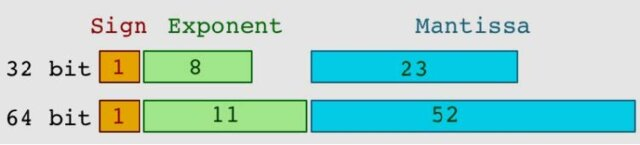 Image taken from: Tarigan, Jos & Zamzami, Elviawaty & Laurent Ginting, Cindy. (2018). Performance Analysis of BigDecimal Arithmetic Operation in Java. Journal of ICT Research and Applications. 12. 267. 10.5614/itbj.ict.res.appl.2018.12.3.5. 

**Activity:** Find the largest and smallest positive values that can be represented with the `double` data type by using the `realmax` and `realmin` functions, respectively.

#### 2.1.2. Integers

#### 2.1.3. Complex


$$\textrm{var}\_\textrm{name}=\mathbb{R}e+\mathbb{I}m$$


Example: 

Can be created by using the `complex` function.

x = 2 + 3i

x = 2.0000 + 3.0000i

y = complex(5, 8)

y = 5.0000 + 8.0000i

real(y)

ans = 5

imag(y)

ans = 8

#### 2.1.4. Infinity

Represented with the function `Inf`

Examples of when you get Inf

x = 1/0

x = Inf

y = 1.e1000

y = Inf

z = exp(1000)

z = Inf

w = log(0)

w = -Inf

#### 2.1.5. NaN

Values that are not real or complex numbers

`NaN = `Not a Number

x = 0/0

x = NaN

### 2.2. Characters and Strings

In MATLAB, **characters** and **strings** are data types used to store textual data:

- A **character** array stores individual characters and is defined with single quotes `' '`.

- A **string** is a modern data type introduced in recent MATLAB versions, defined with double quotes `" "`.

**Examples**:

% Character array (traditional method)
myCharArray = 'Hello, MATLAB!'

myCharArray = 'Hello, MATLAB!'


% String (recommended method)
myString = "Hello, MATLAB!"

myString = "Hello, MATLAB!"

**Accessing Characters**:

- For character arrays, indexing works similarly to numeric arrays:

letter = myCharArray(1)

letter = 'H'

- Strings are treated as scalar, so accessing individual characters requires curly braces `{}` or converting to a char:

letter = myString{1}(1)

letter = 'H'

letter2 = char(myString)

letter2 = 'Hello, MATLAB!'

letter2 = letter2(1)

letter2 = 'H'

**Concatenation**:

str1 = "Biomedical";
str2 = "Engineering";

% Concatenate strings with space
combinedStr = str1 + " " + str2

combinedStr = "Biomedical Engineering"

**Useful Functions**:

- `strlength`: Get the length of strings.

- `contains`: Check if a string contains a substring.

- `upper`, `lower`: Change string case.

len = strlength(combinedStr)

len = 22

isPresent = contains(combinedStr, "Eng")

isPresent = logical
   1


upperStr = upper(combinedStr)

upperStr = "BIOMEDICAL ENGINEERING"

### 2.3. Boolean

Boolean values in MATLAB represent logical states: `true` or `false`. They are often the result of logical operations and comparisons.

**Logical Operators**:

- Equal: `==`

- Not equal: `~=`

- Greater than, less than: `>`, `<`

- Logical AND, OR, NOT: `&&`, `||`, `~`

**Examples**:

a = 10;
b = 5;

isGreater = a > b

isGreater = logical
   1


isEqual = a == b

isEqual = logical
   0


logicalAnd = (a > b) && (b == 5)

logicalAnd = logical
   1


logicalOr = (a < b) || (b == 5)

logicalOr = logical
   1


logicalNot = ~(a == b)

logicalNot = logical
   1


### 2.4. Tables

Tables in MATLAB organize heterogeneous data (different types) into a structured format. Useful for biomedical data like experimental results, patient records, or sensor readings.

**Creating Tables**:

% Sample data
Subject = ["S1"; "S2"; "S3"];
Age = [23; 27; 30];
Height_cm = [175; 168; 180];

% Create a table
bioTable = table(Subject, Age, Height_cm);
bioTable

bioTable = 3×3 table
    Subject    Age    Height_cm
    _______    ___    _________

     "S1"      23        175   
     "S2"      27        168   
     "S3"      30        180   


**Table Operations**:

- Access data by column names:

ages = bioTable.Age

ages =     23
    27
    30


- Add a new column:

Weight_kg = [70; 65; 80];
bioTable.Weight_kg = Weight_kg;
bioTable

bioTable = 3×4 table
    Subject    Age    Height_cm    Weight_kg
    _______    ___    _________    _________

     "S1"      23        175          70    
     "S2"      27        168          65    
     "S3"      30        180          80    


- Filter rows based on conditions:

olderSubjects = bioTable(bioTable.Age > 25, :)

olderSubjects = 2×4 table
    Subject    Age    Height_cm    Weight_kg
    _______    ___    _________    _________

     "S2"      27        168          65    
     "S3"      30        180          80    


- View table summary:

summary(bioTable)


bioTable: 3×4 table

Variables:

    Subject: string
    Age: double
    Height_cm: double
    Weight_kg: double

Statistics for applicable variables:

                 NumMissing      Min      Median       Max          Mean           Std    

    Subject          0                                                                    
    Age              0            23         27         30         26.6667        3.5119  
    Height_cm        0           168        175        180        174.3333        6.0277  
    Weight_kg        0            65         70         80         71.6667        7.6376  



### 2.5. Structures

Structures (`struct`) are data types that store data using named fields. Ideal for grouping related information like patient demographics or sensor configurations.

**Creating Structures**:

% Creating a simple structure
patient.ID = 'P001';
patient.Age = 45;
patient.Diagnosis = 'Hypertension';
patient

patient = struct with fields:
           ID: 'P001'
          Age: 45
    Diagnosis: 'Hypertension'


**Structure Arrays**:

Useful for multiple entries:

patients(1).ID = 'P001';
patients(1).Age = 45;
patients(1).Diagnosis = 'Hypertension';

patients(2).ID = 'P002';
patients(2).Age = 38;
patients(2).Diagnosis = 'Healthy';
patient

patient = struct with fields:
           ID: 'P001'
          Age: 45
    Diagnosis: 'Hypertension'


**Accessing Data**:

- Field access:

agePatient1 = patients(1).Age

agePatient1 = 45

- Get all values from one field:

allAges = [patients.Age]

allAges =     45    38


**Nested Structures**:

Organizing detailed data:

sensor.name = 'Accelerometer';
sensor.specs.range = '±16g';
sensor.specs.samplingRate = 100;
sensor

sensor = struct with fields:
     name: 'Accelerometer'
    specs: [1×1 struct]


Accessing nested structures:

samplingRate = sensor.specs.samplingRate

samplingRate = 100

## 3. Vectors and Matrices

Define row and column vectors:

x = [1 2 3];       % Row
y = [1; 2; 3];     % Column

Access elements: 

x(2)

ans = 2

y(3)

ans = 3

Use functions: 

length(x)

ans = 3

size(y)

ans =      3     1


mean(x)

ans = 2

std(x)

ans = 1

**Exercise:**

Create a 3x3 matrix and:

- Extract the second row

- Calculate the determinant

- Add 2 to every element using vectorized code

## 4. Plotting Basics

Use plot(x, y) for 2D plots:

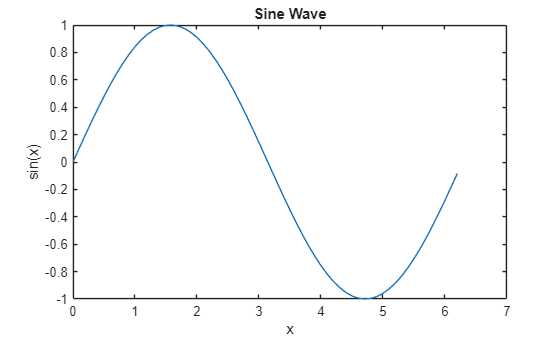

x = 0:0.1:2*pi;
y = sin(x);

plot(x, y)
xlabel('x'); ylabel('sin(x)');
title('Sine Wave');

Customize with grid on, axis, legend, hold on

**Challenge:**

Plot both sin(x) and cos(x) on the same figure. Label them and add a legend.

## 5. Logical Indexing and Conditions

Use logical operators: >, <, ==, ~, &, |

Filter arrays:

A = [3 5 7 9 11];
A(A > 6)

ans =      7     9    11


### 5.1. Conditional statements

#### 5.1.1. `if, ifelse, else`

if mod(x,2) == 0
    disp('Even')
else
    disp('Odd')
end

Odd


#### 5.1.2. `switch, case, otherwise`

switch class(x)
    case 'string'
        disp("This is a string")
    case 'double'
        disp("This is a double")
    case 'table'
        disp("This is a table")
    otherwise
        disp("Nothing")
end

This is a double


**Try This:** Write a script that takes a number and says whether it's positive, negative, or zero.6.

### 5.2. Loops

#### 5.2.1. `for`

for i = 1:5
    disp(i^2)
end

     1

     4

     9

    16

    25



#### 5.2.2. `while`

i = 1;
while i <= 5
    disp(i^2)
    i = i + 1;
end

     1

     4

     9

    16

    25



**Practice Task: **Write a loop that sums all numbers from 1 to 100.

## 6. Using Help and Documentation

Try `help`, `doc`, or clicking on functions in the Editor

Explore the Live Editor Tasks

**Exploration:** Find and summarize what the function `linspace` does. Create a plot using it.

## Summary

You learned how to define and manipulate variables, plot data, apply logical indexing, and use programming constructs.

You explored the MATLAB interface and documentation tools.

## Revision History

## References

- MathWorks. *MATLAB 2025a Documentation*. The MathWorks, Inc. Available: [https://www.mathworks.com/help/matlab/](https://www.mathworks.com/help/matlab/)